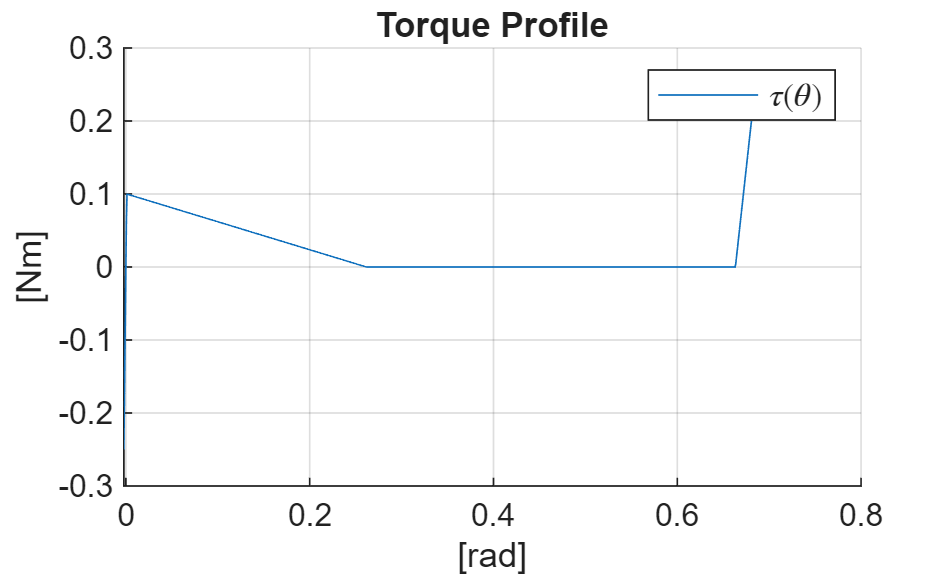

clc
clear
close all

% SPRING PARAMS
d0 = 27.5e-3; % [m]
k = 1.75e3; % [N/m]
d_max = 40e-3; % [m]
SF = 1.1; % [-]

% TORQUE PROFILE POINTS (deg, Nm)
P = [-0.25 -0.25
      0.1   0.1
      30    0.0
      76    0.0
      78    0.2];

P(:,1) = P(:,1)/2/180*pi; % convert to rads
x = linspace(min(P(:,1)), max(P(:,1)),1e3); % angle vector
hx = x(2) - x(1); % discrete step for integration

t = interp1(P(:,1),P(:,2),x); % piecewise linear torque from points in P

% Plotting
figure
hold on
plot(x,t)
title('Torque Profile')
xlabel('[rad]')
ylabel('[Nm]')
legend({'$\tau(\theta)$'},"Interpreter","latex","FontSize",10)
grid on

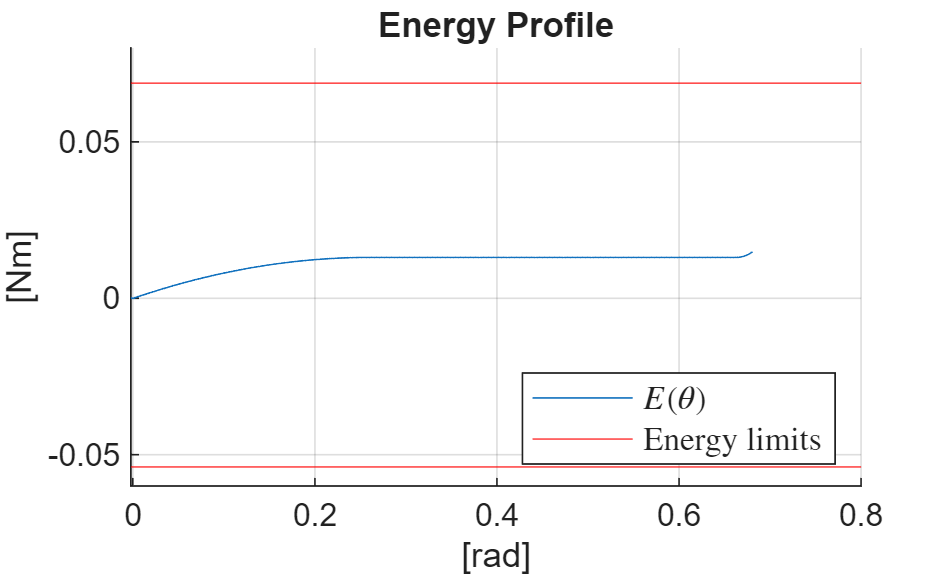

% Energy Profile
% > 0: energy is stored in the spring by an external torque
% < 0: energy is released by the spring
E = cumtrapz(x,t);
% define the integration constant
E = E - interp1(x,E,0);

% Energy landscape scaling factor
alpha = min([1, ...
             (k/2)*(d_max/SF - d0)^2/(max(E)), ...
             (k/2)*(d_max/SF - d0)^2/(max(E) - min(E))]);

% Safety tolerance
eps = 1e-6;
if alpha < 1; alpha = alpha - eps; end

% Support function constant. Determines how much energy is initially stored
r0 = 0.5*(d0 + ((d_max/(SF) - d0)^2 - 2*alpha*max(E)/k).^(1/2));

% Energy landsacpe bounds
Emax = (k/2)*(d_max/SF - d0)^2; % Cannot store more energy than E @ dmax/SF
Emin = -(k/2)*(2*r0 - d0)^2; % Spring cannot release more energy than what was stored

% Plotting
figure
hold on
plot(x,E)
yline(Emax,'r')
yline(Emin,'r')
title('Energy Profile')
xlabel('[rad]')
ylabel('[Nm]')
grid on
legend({'$E(\theta)$','Energy limits'},"Interpreter","latex","FontSize",10,"Location","southeast")

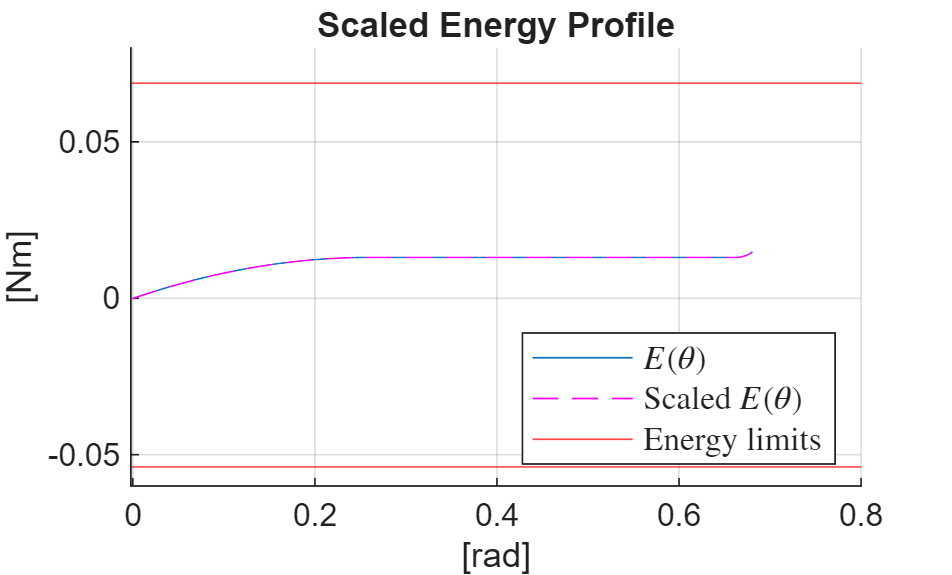


% Scale the energy landscape according to energy landscape bounds
ts = t*alpha;
Es = E*alpha;
dts = gradient(ts, hx);

% Plotting
figure
hold on
plot(x,E)
plot(x,Es,'m--')
yline(Emax,'r')
yline(Emin,'r')
title('Scaled Energy Profile')
xlabel('[rad]')
ylabel('[Nm]')
grid on
legend({'$E(\theta)$','Scaled $E(\theta)$','Energy limits'},"Interpreter","latex","FontSize",10,"Location","southeast")

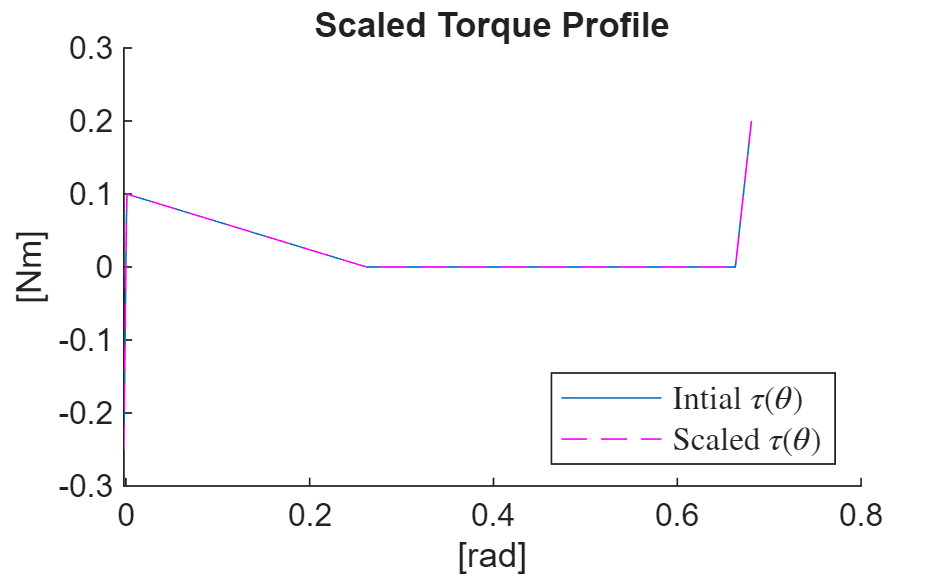


figure
hold on
plot(x,t)
plot(x,ts,'m--')
title('Scaled Torque Profile')
xlabel('[rad]')
ylabel('[Nm]')
legend({'Intial $\tau(\theta)$','Scaled $\tau(\theta)$'},"Interpreter","latex","FontSize",10,"Location","southeast")

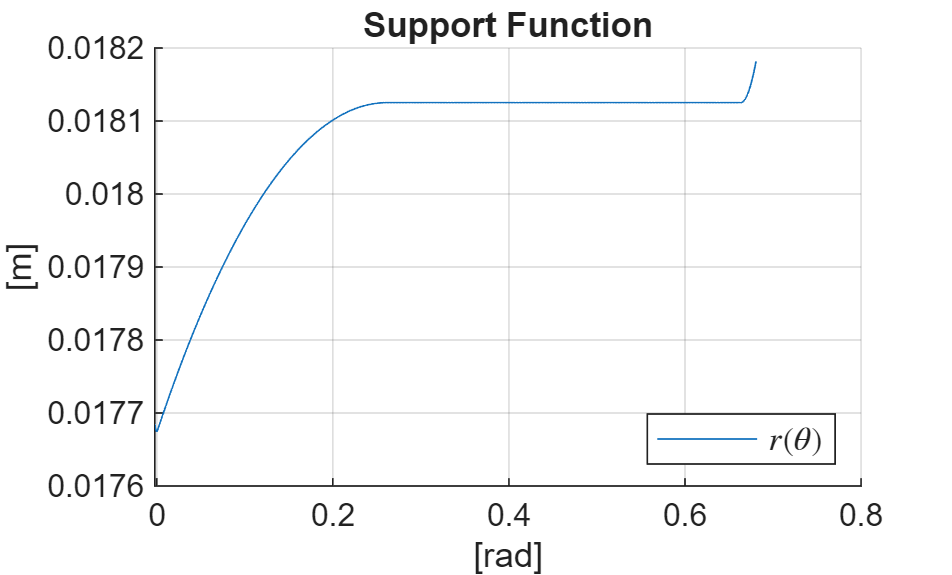

% Support function r(x) to generate the profile
r = 0.5*(d0 + ((2*r0 - d0)^2 + 2*Es/k).^(1/2));

% Plotting
figure
hold on
plot(x,r)
title('Support Function')
xlabel('[rad]')
ylabel('[m]')
legend('$r(\theta)$',"Interpreter","latex","FontSize",10,"Location","southeast")
grid on

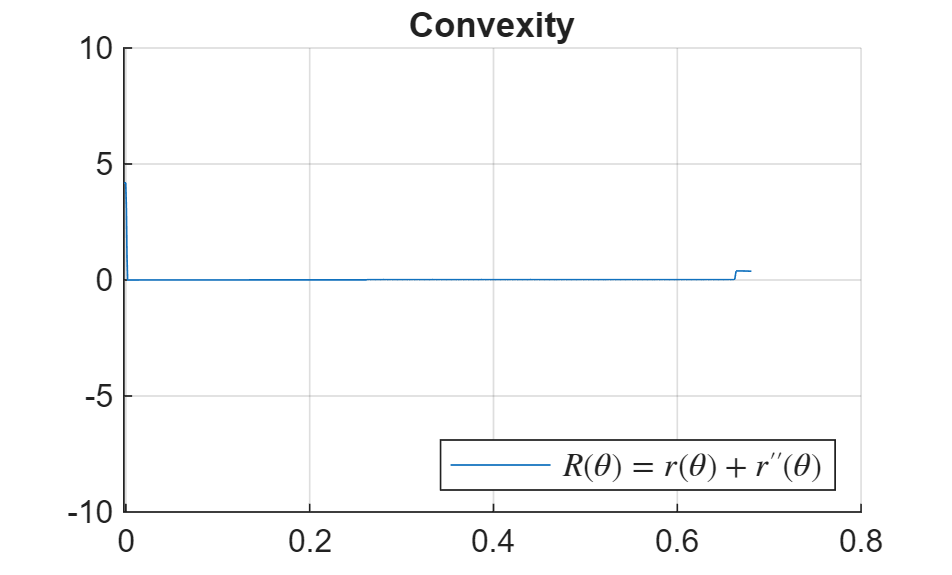

% Derivatives of the support function
dr = ts./(2*k*((d0 - 2*r0)^2 + (2*Es)/k).^(1/2)); % r'(x)
ddr = dts./(2*k*((d0 - 2*r0)^2 + (2*Es)/k).^(1/2)) - ts.^2./(2*k^2*((d0 - 2*r0)^2 + (2*Es)/k).^(3/2)); % r''(x)

% For a convex shape generated by a support function r(x),
% the radius of curvature R(x) must be >= 0
R = r + ddr;

% Plotting
figure
hold on
plot(x,R)
ylim([-10 10])
title('Convexity')
grid on
legend({'$R(\theta) = r(\theta) + r''''(\theta)$'},"Interpreter","latex","FontSize",10,"Location","southeast")

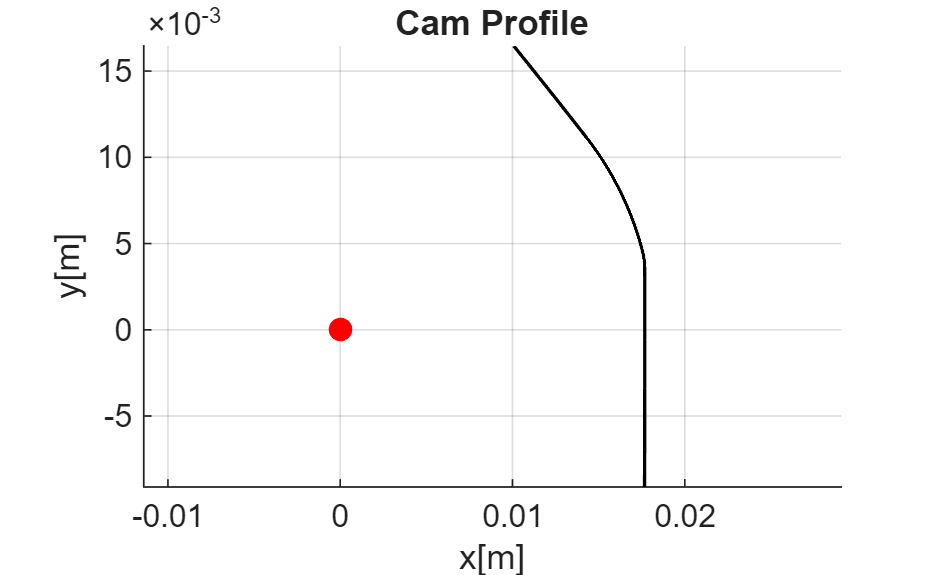

% For a convex curve generated by its support function r(x), the (X,Y)
% coordinates of the profile are given by
xc = r.*cos(x) - dr.*sin(x);
yc = r.*sin(x) + dr.*cos(x);

% Plotting
figure
hold on
plot(xc,yc,'k','LineWidth',1)
scatter(0,0,50,'filled','or')
title('Cam Profile')
xlabel('x[m]')
ylabel('y[m]')
axis equal
grid on

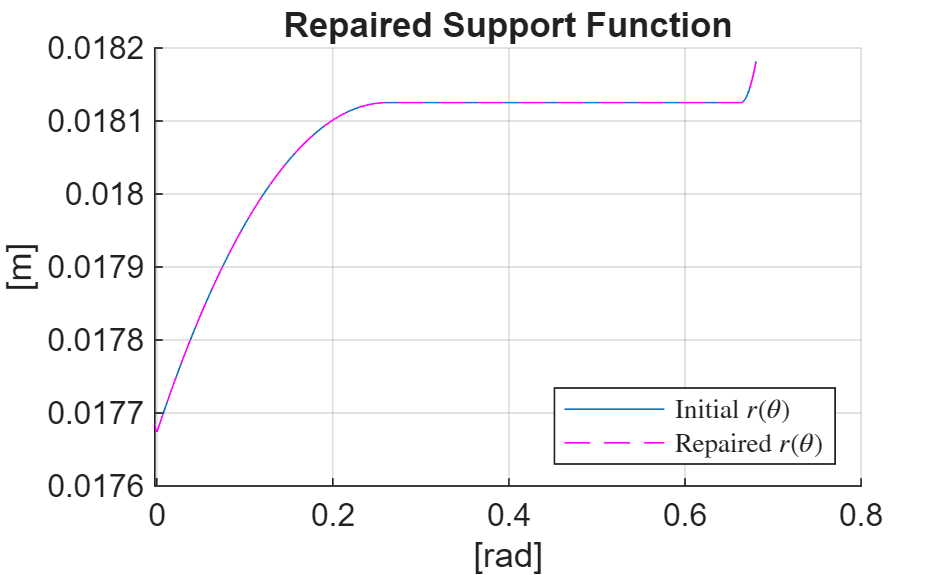

% Repair the support function to satisfy convexity
if min(R) < 0
    eps_val = 1e-3;
    [r_new, dr_new, ddr_new]  = repair_support_function(x, r, dr, ddr, eps_val);
    t_new = 2*k*(2*r_new - d0).*dr_new;
else
    r_new = r;
    dr_new = dr;
    ddr_new = ddr;
    t_new = t;
end

% Repaired radius of curvature
R_new = r_new + ddr_new;

% Plotting
figure
hold on
plot(x,r)
plot(x,r_new,'m--')
title('Repaired Support Function')
xlabel('[rad]')
ylabel('[m]')
legend({'Initial $r(\theta)$','Repaired $r(\theta)$'},"Interpreter","latex","FontSize",8,"Location","southeast")
grid on

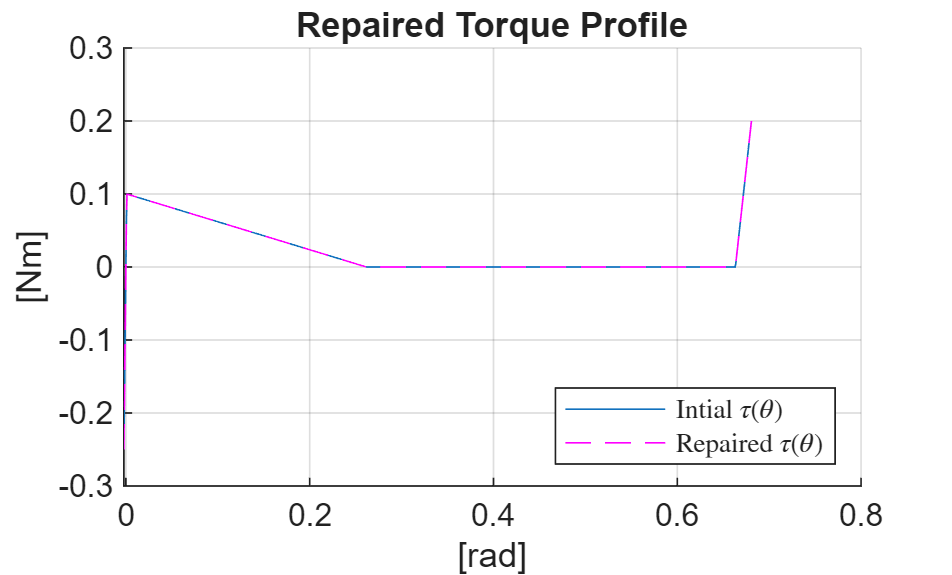


figure
hold on
plot(x,t)
plot(x,t_new,'m--')
title('Repaired Torque Profile')
xlabel('[rad]')
ylabel('[Nm]')
legend({'Intial $\tau(\theta)$','Repaired $\tau(\theta)$'},"Interpreter","latex","FontSize",8,"Location","southeast")
grid on

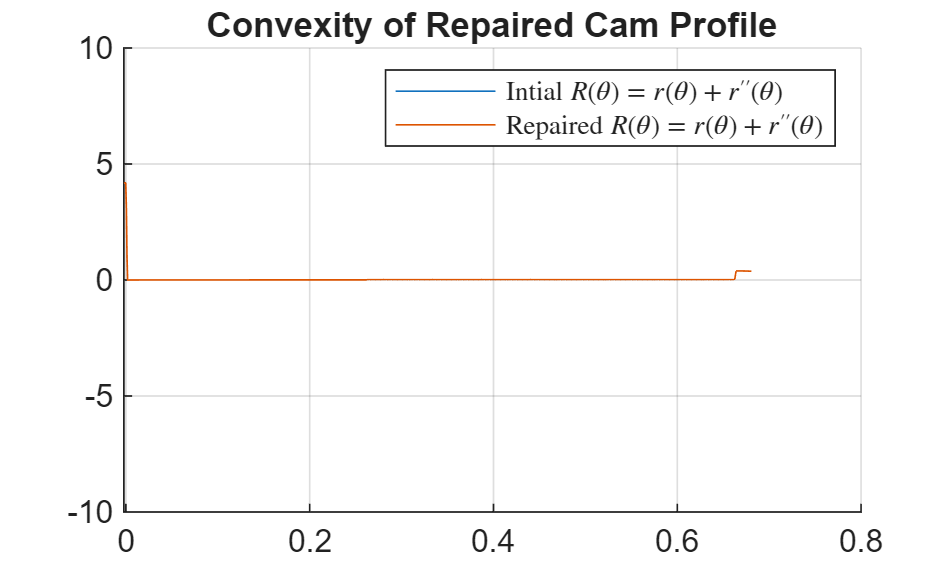



figure
hold on
plot(x,R)
plot(x,R_new)
title('Convexity of Repaired Cam Profile')
ylim([-10 10])
grid on
legend({'Intial $R(\theta) = r(\theta) + r''''(\theta)$', 'Repaired $R(\theta) = r(\theta) + r''''(\theta)$'},"Interpreter","latex","FontSize",8,"Location","northeast")

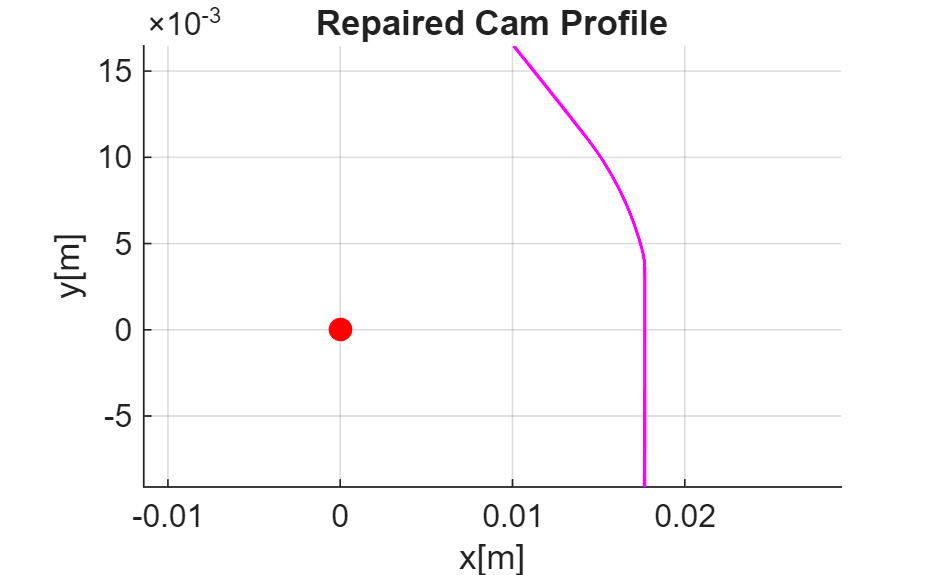

% Repaired cam Profile
xc_new = r_new.*cos(x) - dr_new.*sin(x);
yc_new = r_new.*sin(x) + dr_new.*cos(x);

% Plotting
figure
hold on
plot(xc,yc,'k','LineWidth',0.1)
plot(xc_new,yc_new,'m','LineWidth',1)
scatter(0,0,50,'filled','or')
title('Repaired Cam Profile')

xlabel('x[m]')
ylabel('y[m]')
axis equal
grid on

% RMSE between the target torque response and the achieved torque response
fprintf("Torque profile RMSE: %.6f\n",rmse(t_new,t));

Torque profile RMSE: 0.000000
